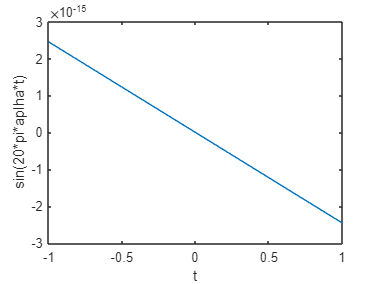

alpha=1+mod(111,3);
t=-1:1;
y=sin(20*pi*alpha*t);
plot(t,y)

xlabel("t")
ylabel("sin(20*pi*aplha*t)")

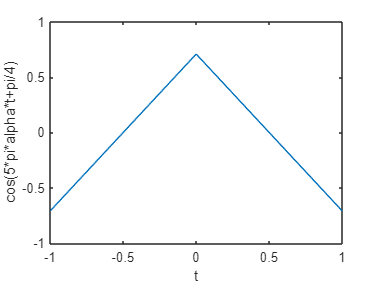

y=cos(5*pi*alpha*t+pi/4);
plot(t,y)

xlabel("t")
ylabel("cos(5*pi*alpha*t+pi/4)")

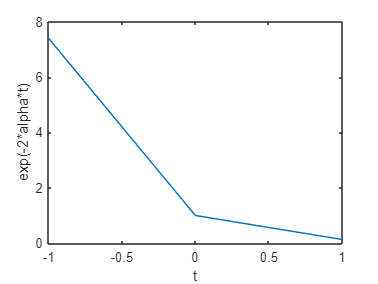

y=exp(-2*alpha*t);
plot(t,y)

xlabel("t")
ylabel("exp(-2*alpha*t)")

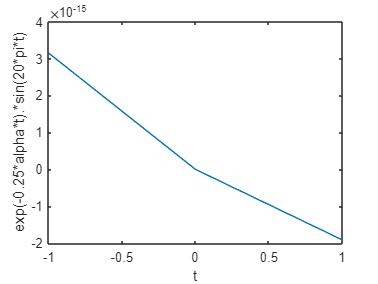

y=exp(-0.25*alpha*t).*sin(20*pi*t);
plot(t,y)

xlabel("t")
ylabel("exp(-0.25*alpha*t).*sin(20*pi*t)")

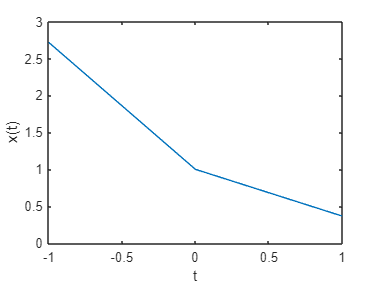

alpha=1+mod(111,3);
x=inline('exp(-(1*t))','t');
plot(t,x(t))

xlabel("t")
ylabel("x(t)")

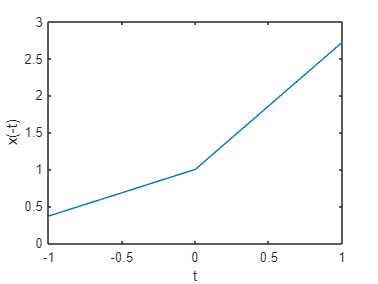

plot(t,x(-t))

xlabel("t")
ylabel("x(-t)")

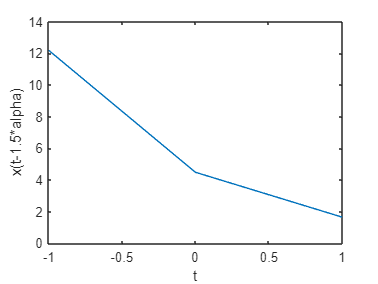

plot(t,x(t-1.5*alpha))

xlabel("t")
ylabel("x(t-1.5*alpha)")

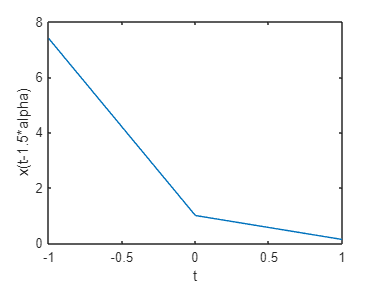

plot(t,x(2*alpha*t))

xlabel("t")
ylabel("x(t-1.5*alpha)")

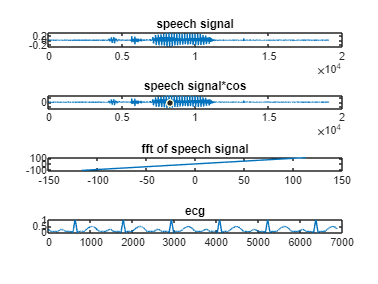

ecg=load('ECG_Data.txt');
plot(ecg)

title("ecg")

Jan=load('RainFallIndia_Jan.txt');
July=load('RainFallIndia_July.txt');
a=6

a = 6

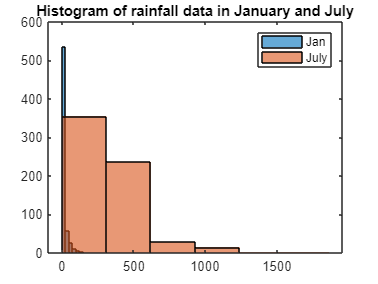

histogram(Jan,a)
hold on
histogram(July,a)
hold off
title("Histogram of rainfall data in January and July")
legend("show")

m=[Jan;July];
Mean=mean(m)

Mean = 172.2224

Standarddeviaton=std(m)

Standarddeviaton = 220.0828

[y Fs]=audioread('Track001.wav');
sound(y,Fs)

filename = 'speech.wav';  % Replace with the actual sampling frequency

% Read the speech signal
[s, Fs_s] = audioread(filename);

F=250;
y=s.*cos(2*pi*F/Fs_s);
sound(y,Fs_s);
n=0:length(s)-1;
subplot(4,1,1)
plot(n,s)
subplot(4,1,2)
plot(n,y)


S=fft(s);
Y=fft(y);
subplot(4,1,3)
plot(S,Y)

subplot(4,1,4)
corr=xcorr(s,y)

corr =     0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


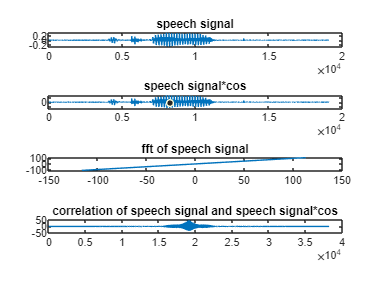

plot(corr)

subplot(4,1,1)
title("speech signal")
subplot(4,1,2)
title("speech signal*cos")
ax = gca;
chart = ax.Children(1);
datatip(chart,8321,-0.01403);
subplot(4,1,3)
title("fft of speech signal")
subplot(4,1,4)
title("correlation of speech signal and speech signal*cos")

t=[0:0.001:5];
a=sin(200*t);
b=sin(220*t);
c=[a,b];

filename='convaluted_signal.wav';
audiowrite(filename,c,44100)
[y Fs]=audioread("convaluted_signal.wav");
sound(y,Fs)



% Frequencies corresponding to Do Re Mi Fa So La Ti Do
frequencies = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25]; % Hz
time=0:0.001:5;
combined_signal = [];
for i = 1:length(frequencies)
    tone = sin(2 * pi * frequencies(i) * time);
    combined_signal = [combined_signal, tone];
end
filename='convaluted_signal2.wav';
audiowrite(filename,combined_signal,7000)
[y Fs]=audioread("convaluted_signal2.wav");
sound(y,Fs)

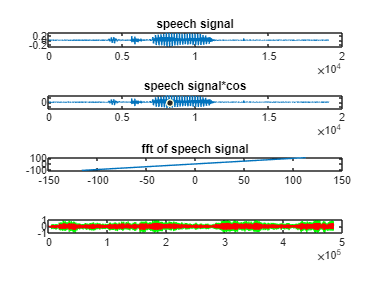

a=audioread('Track001.wav');
b=load('ConvFile1.txt');
c=conv(a,b);
max_amplitude=max(max(c),abs(min(c)));
c=c/max_amplitude;
filename='convaluted_signal1.wav';
audiowrite(filename,c,44100)
[y Fs]=audioread("convaluted_signal1.wav");
sound(y,Fs)
t=0:length(a)-1;
%subplot(2,1,1)
%plot(t,a)
t1=0:length(c)-1;
%subplot(2,1,2)
plot(t1,c,'g',t,a,'r')